beta=1430;
alpha= 7600;
phi=0.51;
theta=2.5;
lambda=2470;
Mu=7200;
Q=10000;
Nu=139000;

## **Normal function**

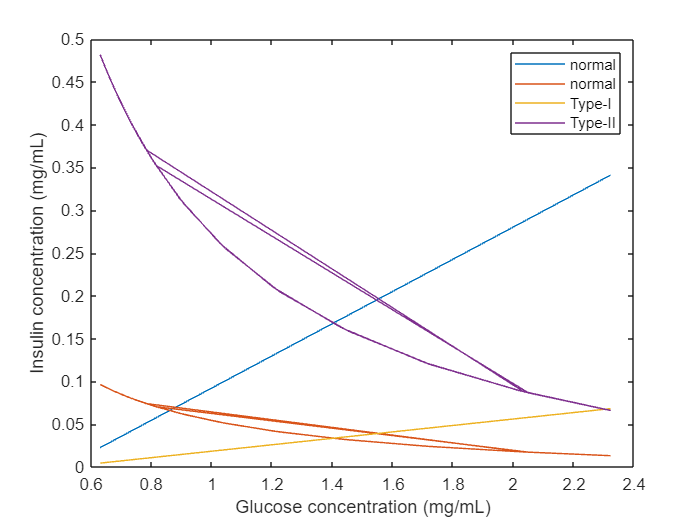

X=x;
if X<=phi
    Y1=0;
else 
    Y1=(beta/alpha).*(X-phi);
end

if X<=theta
    Y2=(Q-lambda*X)./(Nu*X);
else
    Y2=(Q-lambda*X-Mu*(X-theta))./(Nu*X);
end
figure
plot(X,Y1)
hold on
plot(X,Y2)

reduced_beta=0.2*beta;
if X<=phi
    Y3=0;
else 
    Y3=(reduced_beta/alpha).*(X-phi);
end
plot(X,Y3)
reduced_nu=0.2*Nu;
if X<=theta
    Y4=(Q-lambda*X)./(reduced_nu*X);
else
    Y4=(Q-lambda*X-Mu*(X-theta))./(reduced_nu*X);
end
plot(X,Y4)
legend('normal','normal','Type-I','Type-II')
xlabel('Glucose concentration (mg/mL)')
ylabel('Insulin concentration (mg/mL)')